## **Mobile Health Text Misinformation Detection Using Effective Information Retrieval Methods**

warning('off','MATLAB:ClassInstanceExists')
clear classes
mod = py.importlib.import_module('LCSProjectPython');
py.importlib.reload(mod);

modLACS = py.importlib.import_module('LACSProjectPython');
py.importlib.reload(modLACS);

modPhrase = py.importlib.import_module('PhraseProjectPython');
py.importlib.reload(modPhrase);

modKeywordMatching = py.importlib.import_module('KeywordMatchingProjectPython');
py.importlib.reload(modKeywordMatching);

**Keywork Matching**

Similarity = # of common Elements

py.KeywordMatchingProjectPython.getResult()
T = readtable('KeywordMatchingResult.csv');

T

T = 6×4 table
          Class           Total    KeywordMatchingCorrectPrediction    KeywordMatchingAccuracy
    __________________    _____    ________________________________    _______________________

    {'Disinformative'}      34                    26                             76           
    {'Real'          }      24                    11                             46           
    {'Fake'          }      52                    49                             94           
    {'MisInformative'}      35                    24                             69           
    {'Unverified'    }      44                    26                             59           
    {'Total'         }     189                   136                             72           


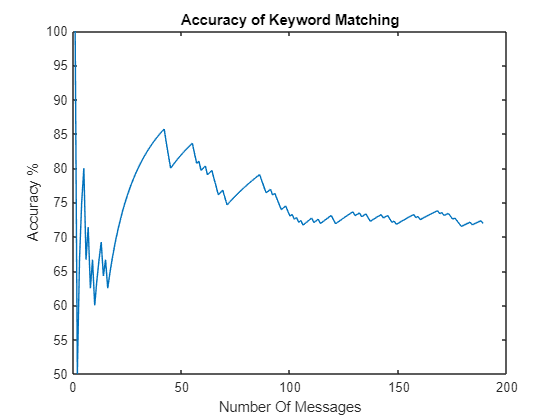


T = readtable('PlotKeywordMatching.csv');
X=T{:,1};
Y=T{:,2};
savefig('KeywordMatchingdata.fig');
close(gcf);
%openfig('LCSdata.fig')
plot(X,Y)
title('Accuracy of Keyword Matching')
xlabel('Number Of Messages') 
ylabel('Accuracy %') 

**Longest Common Subsequence (LCS)**

Similarity = # of connections

py.LCSProjectPython.getResult()
T = readtable('LCSResult.csv');
T

T = 6×4 table
          Class           Total    LCSCorrectPrediction    LCSAccuracy
    __________________    _____    ____________________    ___________

    {'Disinformative'}      34              18                 53     
    {'Real'          }      24               9                 38     
    {'Fake'          }      52              43                 83     
    {'MisInformative'}      35              17                 49     
    {'Unverified'    }      44              28                 64     
    {'Total'         }     189             115                 61     


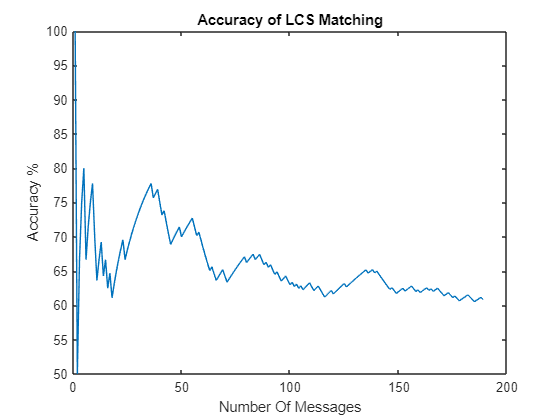

T = readtable('PlotLCS.csv');
X=T{:,1};
Y=T{:,2};
savefig('LCSdata.fig');
close(gcf);
%openfig('LCSdata.fig')
plot(X,Y)
title('Accuracy of LCS Matching')
xlabel('Number Of Messages') 
ylabel('Accuracy %') 

**Longest Approximate Common Subsequence (LACS)**

Similarity = Weight*(# of connections) – (# of crossings) ⁄ (# of connections)

py.LACSProjectPython.getResult()
T = readtable('LACSResult.csv');
T

T = 6×4 table
          Class           Total    LACSCorrectPrediction    LACSAccuracy
    __________________    _____    _____________________    ____________

    {'Disinformative'}      34               27                  79     
    {'Real'          }      24               10                  42     
    {'Fake'          }      52               50                  96     
    {'MisInformative'}      35               23                  66     
    {'Unverified'    }      44               31                  70     
    {'Total'         }     189              141                  75     


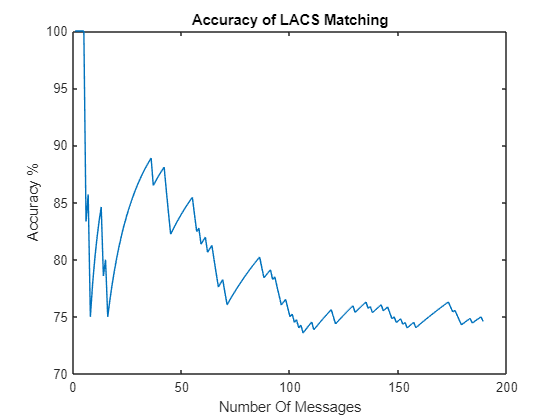

T = readtable('PlotLACS.csv');
X=T{:,1};
Y=T{:,2};
savefig('LACSdata.fig');
close(gcf);
%openfig('LACSdata.fig')
plot(X,Y)
title('Accuracy of LACS Matching')
xlabel('Number Of Messages') 
ylabel('Accuracy %')

**Phrases Matched**

SImilarity=   (# of keywords matched) + 2×(# of phrases matched) + ∑(length of each phrase matched)

py.PhraseProjectPython.getResult()
T = readtable('PhraseResult.csv');
T

T = 6×4 table
          Class           Total    PhraseMatchedCorrectPrediction    PhraseMatchedAccuracy
    __________________    _____    ______________________________    _____________________

    {'Disinformative'}      34                   23                           68          
    {'Real'          }      24                   10                           42          
    {'Fake'          }      52                   46                           88          
    {'MisInformative'}      35                   20                           57          
    {'Unverified'    }      44                   25                           57          
    {'Total'         }     189                  124                           66          


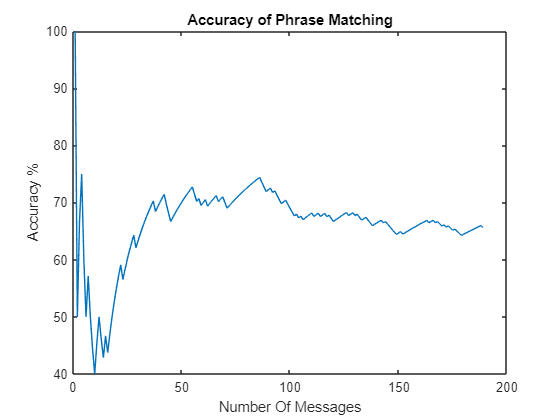

T = readtable('PlotPhrase.csv');
X=T{:,1};
Y=T{:,2};
savefig('Phrasedata.fig');
close(gcf);
%openfig('LACSdata.fig')
plot(X,Y)
title('Accuracy of Phrase Matching')
xlabel('Number Of Messages') 
ylabel('Accuracy %')

**Final Plot:**

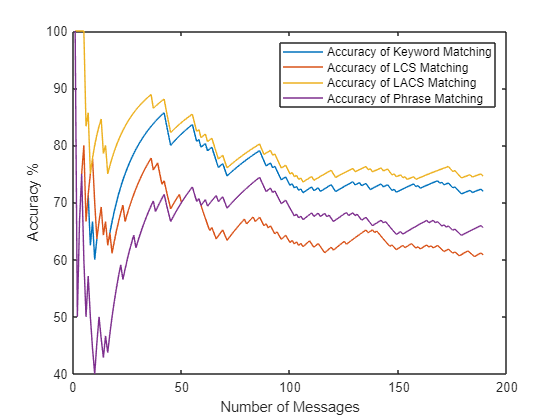

T = readtable('PlotKeywordMatching.csv');
X=T{:,1};
Y=T{:,2};
plot(X,Y)
 

hold on 
TLCS = readtable('PlotLCS.csv');
XLCS=TLCS{:,1};
YLCS=TLCS{:,2};
plot(XLCS,YLCS)

TLACS = readtable('PlotLACS.csv');
XLACS=TLACS{:,1};
YLACS=TLACS{:,2};
plot(XLACS,YLACS)

TPhrase = readtable('PlotPhrase.csv');
XPhrase=TPhrase{:,1};
YPhrase=TPhrase{:,2};
plot(XPhrase,YPhrase)


legend('Accuracy of Keyword Matching' ,'Accuracy of LCS Matching' ,'Accuracy of LACS Matching' ,'Accuracy of Phrase Matching')
xlabel('Number of Messages') 
ylabel('Accuracy %')
 
hold off